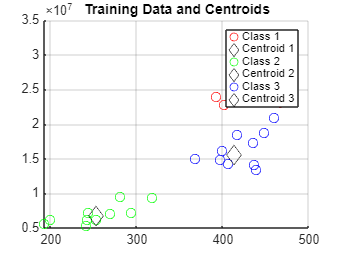



clearvars; close all; clc;

% Cargar el dataset guardado
load('features_and_labels.mat');

N_train = 7;  % Número de vectores por clase para entrenamiento

% Inicializar centroides
numClasses = max(allLabels);  % Número de clases (únicos en allLabels)
m = zeros(size(allFeatures, 1), numClasses);  % Matriz de centroides
S = eye(size(allFeatures, 1));  % Matriz identidad de covarianza

% Calcular centroides para cada clase
for c = 1:numClasses
    % Índices de la clase actual
    idxClass = find(allLabels == c);  
    idxTrain = idxClass(1:N_train);  % Primeros N_train como entrenamiento

    % Calcular el centroide
    m(:, c) = mean(allFeatures(:, idxTrain), 2);
end

% Visualización de puntos de entrenamiento
figure; hold on; grid on;
colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k'};
for c = 1:numClasses
    % Graficar puntos por clase
    idxClass = find(allLabels == c);
    scatter(allFeatures(1, idxClass), allFeatures(2, idxClass), 50, colors{c}, 'DisplayName', ['Class ' num2str(c)]);
    % Graficar centroides
    plot(m(1, c), m(2, c), 'kd', 'MarkerSize', 10, 'DisplayName', ['Centroid ' num2str(c)]);
end


title('Training Data and Centroids');
legend();

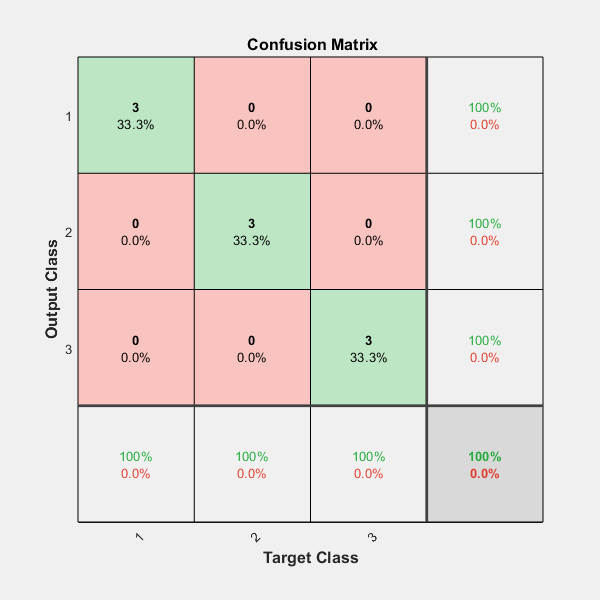


% Clasificar puntos de prueba
N_test = 10 - N_train;  % Restantes para prueba
X_test = [];
class_test = [];

for c = 1:numClasses
    idxClass = find(allLabels == c);
    idxTest = idxClass(N_train+1:end);  % Últimos para prueba
    X_test = [X_test, allFeatures(:, idxTest)];
    class_test = [class_test, c * ones(1, N_test)];
end

predicted_labels = zeros(1, size(X_test, 2));
class_val = zeros(numClasses, size(X_test, 2));  % Etiquetas de prueba en formato binario
class_vtrue = zeros(numClasses, size(X_test, 2));  % Etiquetas predichas en formato binario

for i = 1:size(X_test, 2)
    X = X_test(:, i);
    % Distancias a los centroides
    d = zeros(1, numClasses);
    for c = 1:numClasses
        d(c) = sqrt((X - m(:, c))' * inv(S) * (X - m(:, c))); 
    end
    [~, predicted_labels(i)] = min(d);  % Clase más cercana

    % Convertir etiquetas a formato binario para plotconfusion
    class_vtrue(predicted_labels(i), i) = 1;
    class_val(class_test(i), i) = 1;
end

% Matriz de confusión gráfica
figure;plotconfusion(class_vtrue, class_val);


% Mostrar precisión en consola
accuracy = sum(diag(confusionmat(class_test, predicted_labels))) / length(class_test) * 100;
fprintf('Accuracy: %.2f%%\n', accuracy);

Accuracy: 100.00%
